close all; clear; clc;
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end
clear list_factory index_interpreter default_name i;

%Materials and frequencies

materials = [0.02 0.02 0.02 0.03 0.03 0.04 0.05 0.05 0.05 0.05;
            0.18 0.18 0.12 0.10 0.09 0.08 0.07 0.07 0.07 0.07;
            0.08 0.08 0.24 0.57 0.69 0.71 0.73 0.73 0.73 0.73;
            0.20 0.20 0.15 0.10 0.08 0.04 0.02 0.02 0.02 0.02;
            0.36 0.36 0.26 0.51 0.45 0.62 0.76 0.76 0.76 0.76;
            0.41 0.41 0.67 0.58 0.59 0.68 0.35 0.35 0.35 0.35]

materials =     0.0200    0.0200    0.0200    0.0300    0.0300    0.0400    0.0500    0.0500    0.0500    0.0500
    0.1800    0.1800    0.1200    0.1000    0.0900    0.0800    0.0700    0.0700    0.0700    0.0700
    0.0800    0.0800    0.2400    0.5700    0.6900    0.7100    0.7300    0.7300    0.7300    0.7300
    0.2000    0.2000    0.1500    0.1000    0.0800    0.0400    0.0200    0.0200    0.0200    0.0200
    0.3600    0.3600    0.2600    0.5100    0.4500    0.6200    0.7600    0.7600    0.7600    0.7600
    0.4100    0.4100    0.6700    0.5800    0.5900    0.6800    0.3500    0.3500    0.3500    0.3500



frequencies = [0 125 250 500 1000 2000 4000 8000 16000 22050]

frequencies =            0         125         250         500        1000        2000        4000        8000       16000       22050


%%%Composite Transmission Loss

%Surfaces
floorSurface = 7.790*4.130;
RugSurface = 2.60*4.0;
sideWallsSurface = 2.78*7.790;
endWallsSurface = 4.130*2.78

endWallsSurface = 11.4814


BigTile = 1.80*0.60;
MediumTile = 0.60*1.20;
smallTile = 0.90*0.60;

controllWall = ((endWallsSurface - (2*BigTile) + smallTile) * materials(1,:) + (2*BigTile + smallTile) * materials(6,:))/endWallsSurface

controllWall =     0.1136    0.1136    0.1747    0.1622    0.1645    0.1943    0.1253    0.1253    0.1253    0.1253



doorWall = ((sideWallsSurface - (4*BigTile + smallTile))*materials(1,:) + (smallTile + 4*BigTile) * materials(6,:))/endWallsSurface

doorWall =     0.2028    0.2028    0.3129    0.2894    0.2936    0.3464    0.2213    0.2213    0.2213    0.2213


OuterWall = ((sideWallsSurface - (3*BigTile + 3*smallTile))*materials(1,:) + (3*smallTile + 3*BigTile) * materials(6,:))/endWallsSurface

OuterWall =     0.2028    0.2028    0.3129    0.2894    0.2936    0.3464    0.2213    0.2213    0.2213    0.2213


floor = ((floorSurface-RugSurface) * materials(2,:) + RugSurface*materials(3,:))/floorSurface

floor =     0.1477    0.1477    0.1588    0.2519    0.2840    0.2837    0.2833    0.2833    0.2833    0.2833


new_Materials = [
    controllWall;
    materials(5,:);
    doorWall;
    OuterWall;
    floor;
    materials(4,:);
                ]

new_Materials =     0.1136    0.1136    0.1747    0.1622    0.1645    0.1943    0.1253    0.1253    0.1253    0.1253
    0.3600    0.3600    0.2600    0.5100    0.4500    0.6200    0.7600    0.7600    0.7600    0.7600
    0.2028    0.2028    0.3129    0.2894    0.2936    0.3464    0.2213    0.2213    0.2213    0.2213
    0.2028    0.2028    0.3129    0.2894    0.2936    0.3464    0.2213    0.2213    0.2213    0.2213
    0.1477    0.1477    0.1588    0.2519    0.2840    0.2837    0.2833    0.2833    0.2833    0.2833
    0.2000    0.2000    0.1500    0.1000    0.0800    0.0400    0.0200    0.0200    0.0200    0.0200


%Invert
new_Materials = 1-new_Materials

new_Materials =     0.8864    0.8864    0.8253    0.8378    0.8355    0.8057    0.8747    0.8747    0.8747    0.8747
    0.6400    0.6400    0.7400    0.4900    0.5500    0.3800    0.2400    0.2400    0.2400    0.2400
    0.7972    0.7972    0.6871    0.7106    0.7064    0.6536    0.7787    0.7787    0.7787    0.7787
    0.7972    0.7972    0.6871    0.7106    0.7064    0.6536    0.7787    0.7787    0.7787    0.7787
    0.8523    0.8523    0.8412    0.7481    0.7160    0.7163    0.7167    0.7167    0.7167    0.7167
    0.8000    0.8000    0.8500    0.9000    0.9200    0.9600    0.9800    0.9800    0.9800    0.9800


%Convert to dB
Walls_dB = 20*log10(new_Materials)

Walls_dB =    -1.0474   -1.0474   -1.6682   -1.5368   -1.5612   -1.8762   -1.1623   -1.1623   -1.1623   -1.1623
   -3.8764   -3.8764   -2.6154   -6.1961   -5.1927   -8.4043  -12.3958  -12.3958  -12.3958  -12.3958
   -1.9687   -1.9687   -3.2592   -2.9675   -3.0194   -3.6932   -2.1726   -2.1726   -2.1726   -2.1726
   -1.9687   -1.9687   -3.2592   -2.9675   -3.0194   -3.6932   -2.1726   -2.1726   -2.1726   -2.1726
   -1.3879   -1.3879   -1.5019   -2.5212   -2.9012   -2.8975   -2.8938   -2.8938   -2.8938   -2.8938
   -1.9382   -1.9382   -1.4116   -0.9151   -0.7242   -0.3546   -0.1755   -0.1755   -0.1755   -0.1755




Fs = 44100; % specify the sampling frequency (in Hz)
freq_normal = frequencies/(Fs/2); % normalize the frequencies


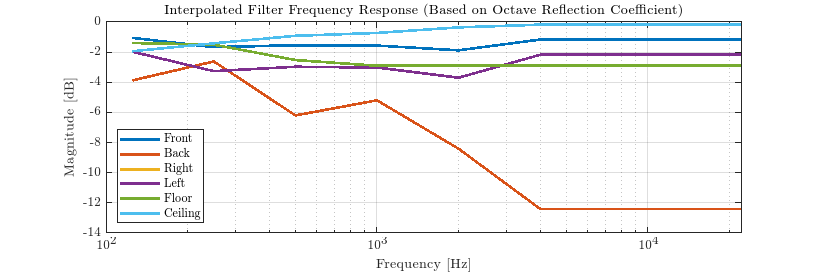


figure('Position', [10 10 900 300]);
semilogx(frequencies,Walls_dB(1,:), 'LineWidth', 2)
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
title('Interpolated Filter Frequency Response (Based on Octave Reflection Coefficient)')
hold on;
grid;
semilogx(frequencies,Walls_dB(2,:), 'LineWidth', 2)
semilogx(frequencies,Walls_dB(3,:), 'LineWidth', 2)
semilogx(frequencies,Walls_dB(4,:), 'LineWidth', 2)
semilogx(frequencies,Walls_dB(5,:), 'LineWidth', 2)
semilogx(frequencies,Walls_dB(6,:), 'LineWidth', 2)
hold off

legend('Front', 'Back', 'Right', 'Left', 'Floor', 'Ceiling', 'Location', 'southwest');
hold off;

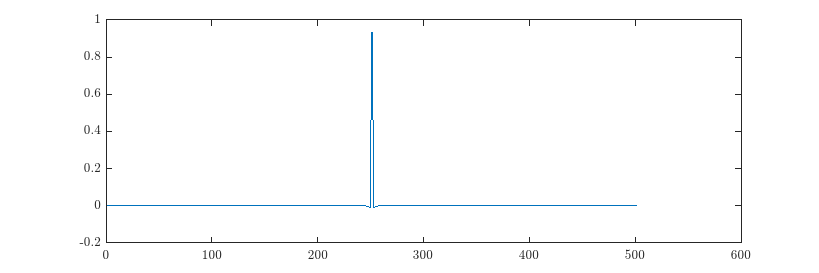

NFront = 500; % Filter order
NBack = 200;
NRightLeft = 200;
NFloor = 200;
NCeiling = 200;

FrontFilter = fir2(NFront, freq_normal, new_Materials(1,:));
BackFilter = fir2(NBack, freq_normal, new_Materials(2,:));
RightLeftFilter = fir2(NRightLeft, freq_normal, new_Materials(3,:));
FloorFilter = fir2(NFloor, freq_normal, new_Materials(5,:));
CeilingFilter = fir2(NCeiling, freq_normal, new_Materials(6,:));

[hFront,wFront] = freqz(FrontFilter, 1, Fs);
[hBack,wBack] = freqz(BackFilter, 1, Fs);
[hRightLeft,wRightLeft] = freqz(RightLeftFilter, 1, Fs);
[hFloor,wFloor] = freqz(FloorFilter, 1, Fs);
[hCeiling,wCeiling] = freqz(CeilingFilter, 1, Fs);

FrontFilterMin = firminphase(FrontFilter);
BackFilterMin = fir2(NBack, freq_normal, new_Materials(2,:));
RightLeftFilterMin = fir2(NRightLeft, freq_normal, new_Materials(3,:));
FloorFilterMin = fir2(NFloor, freq_normal, new_Materials(5,:));
CeilingFilterMin = fir2(NCeiling, freq_normal, new_Materials(6,:));

invFFM = flip(FrontFilterMin);
FrontFilterMin = [invFFM FrontFilterMin];

plot(FrontFilterMin)

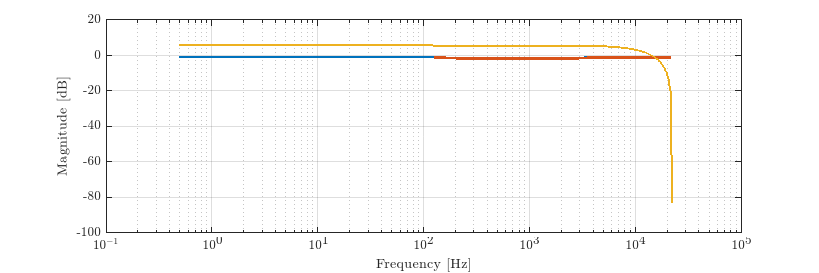


[hFrontMin,wFrontMin] = freqz(FrontFilterMin, 1, Fs);

figure('Position', [10 10 900 300]);
semilogx(wFront*(22050/pi),20*log10(abs(hFront)), 'LineWidth', 2);
grid;
hold on;
semilogx(frequencies,Walls_dB(1,:), 'LineWidth', 2);
semilogx(wFrontMin*(22050/pi),20*log10(abs(hFrontMin)), 'LineWidth', 2);
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
hold off;

x = randn(1, 1000); % create a random signal
y = filter(FrontFilter, 1, x); % apply the filter to the signal
ymin = filter(FrontFilterMin, 1, x); % apply the filter to the signal
y-ymin

ans =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


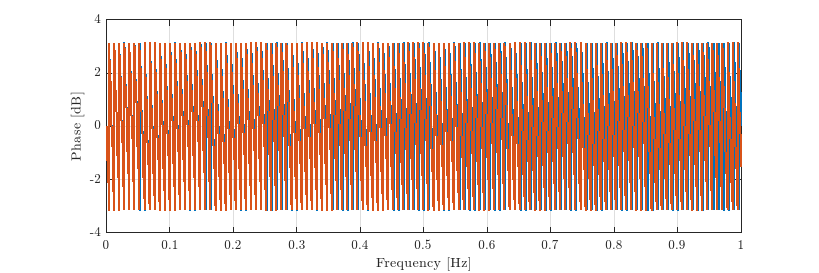


figure('Position', [10 10 900 300]);
plot(wFront/pi,angle(hFront), 'LineWidth', 2);
grid;
hold on;
%semilogx(frequencies,Walls_dB(1,:), 'LineWidth', 2);
plot(wFrontMin/pi,angle(hFrontMin), 'LineWidth', 2);
xlabel('Frequency [Hz]');
ylabel('Phase [dB]');

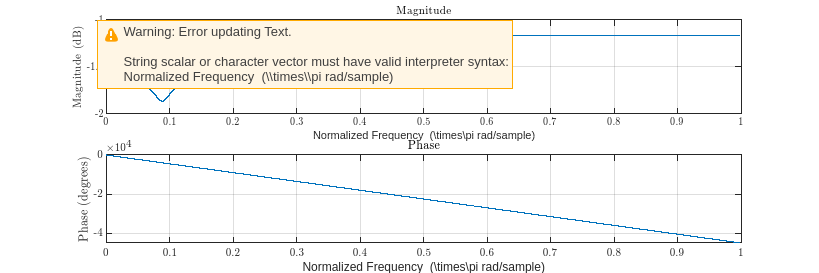

freqz(FrontFilter, 1, Fs);
hold on;

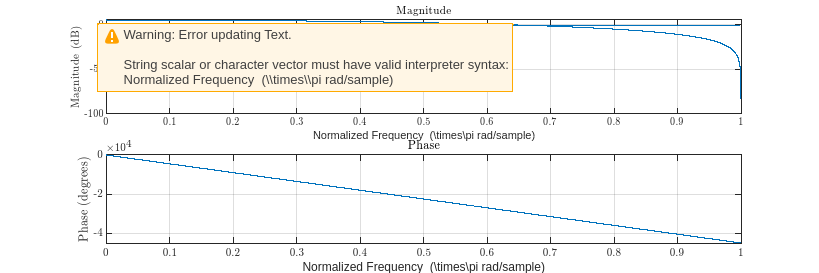

freqz(FrontFilterMin, 1, Fs);
hold off;